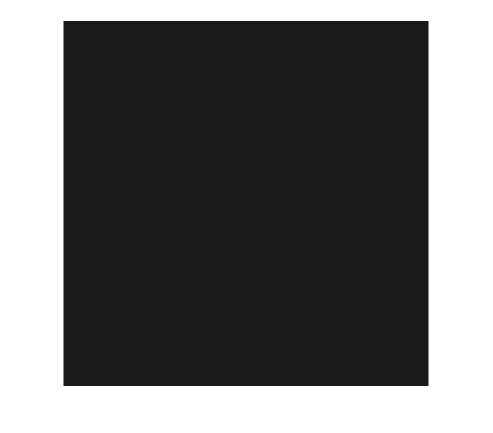

clc
clearvars -except textures

if ~exist('textures', 'var')
    disp("Textures not loaded, loading textures...")
    load("textures\textures.mat");
    disp("done")
end

% Single color image
color = [0.8, 0.2, 0.2];
%color = [0.2, 0.6, 0.2];
%color = [0.6, 0.6, 0.2];
%color = [0.2, 0.6, 0.6];
color = [0.1, 0.1, 0.1];
image = zeros(500, 500, 3);
image(:,:,1) = color(1);
image(:,:,2) = color(2);
image(:,:,3) = color(3);
imshow(image)


%Find matching texture
textureID = rgb2textureID(color, textures)

textureID = 31

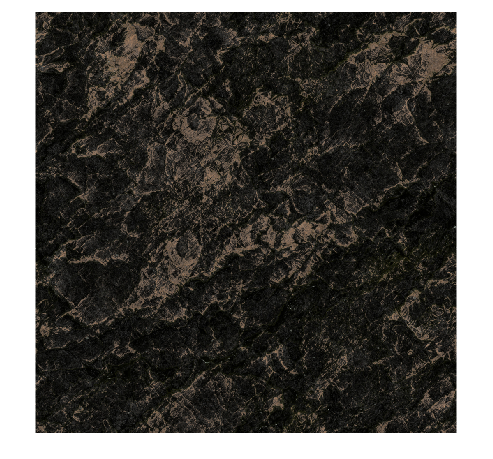


%Display result
result_texture = textures(textureID).diffuse;

imshow(result_texture)